clear;
clc;
set(0,'defaulttextinterpreter','latex');

% Time increment and movement steps
time_increment = 60/110 * 1000; % converting to milliseconds
steps_left = 5;
steps_up = 6;
steps_right = 5;
steps_down = 6;
movement_distance = 0.7;

% Define the corners of the ground truth rectangle
x_true = [0, 3.50, 3.50, 0, 0];
y_true = [0.40, 0.40, 4.60, 4.60, 0.40];

node_x = [0, 3.5, 1.75];
node_y = [0, 0, 5.30];

figure;
idx = 1;
subplot_idx_raw = 1;
subplot_idx_filt = 2;

Colours = [
    0 0 1;
    0 1 0;
    1 0 1;
    0.34, 0.70, 0.91;
    0, 0.62, 0.45;
    0.80, 0.47, 0.65
    ];

KF_1 = {'$Q$ = 0.01, $R$ = 100', '$Q$ = 0.1, $R$ = 100', '$Q$ = 0.01, $R$ = 10', '$Q$ = 0.01, $R$ = 50', '$Q$ = 0.01, R = 200', '$Q$ = 0.001, $R$ = 100'};

% Loop through each file
for fileNum = 1:6
    % Construct the filename
    filename = sprintf('KF_FC132_Final%d.txt', fileNum);
    
    % Initialise arrays to hold the x, y, and t data
    x = [];
    y = [];
    t = [];
    
    % Open the file for reading
    fid = fopen(filename, 'r');
    
    % Read the file line by line
    while ~feof(fid)
        line = fgetl(fid);
        if line == -1
            break;
        end
        % Use regular expressions to extract the x, y, and t values
        matches = regexp(line, 'x = (?<x>-?\d+\.\d+), y = (?<y>-?\d+\.\d+), t = (?<t>\d+)', 'names');
        if ~isempty(matches)
            x = [x; str2double(matches.x)]; %#ok<*AGROW> 
            y = [y; str2double(matches.y)];
            t = [t; str2double(matches.t)];
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Generate the path taken
    path_x = [3.50];
    path_y = [0.40];
    path_t = [0; t(2)];
    for i = 1:(1000*1000/time_increment)
        if mod(i-1, steps_left + steps_up + steps_right + steps_down) < steps_left
            path_x(end+1, 1) = path_x(end) - movement_distance;
            path_y(end+1, 1) = path_y(end);
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up)
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) + movement_distance;
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up + steps_right)
            path_x(end+1, 1) = path_x(end) + movement_distance;
            path_y(end+1, 1) = path_y(end);
        else
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) - movement_distance;
        end
        path_t(end+1, 1) = path_t(end) + time_increment;
    end
    
    % Initialise error arrays
    error_x = [];
    error_y = [];
    error_t = [];
    total_error = [];
    
    % Find the matching time points and compute the errors
    for i = 1:length(t)
        [~, closestIndex] = min(abs(path_t - t(i)));
        if abs(path_t(closestIndex) - t(i)) <= 500 % time difference in milliseconds
            error_x(end+1, 1) = path_x(closestIndex) - x(i);
            error_y(end+1, 1) = path_y(closestIndex) - y(i);
            error_t(end+1, 1) = path_t(closestIndex) - t(i);
        end
    end

    for i = 1:length(error_x)
        total_error(i, 1) = sqrt(error_x(i).^2 + error_y(i).^2);
    end
    
    % Plot the data and errors for this file
    if fileNum <= 3
        subplot(3, 2, subplot_idx_raw)
        plot(x, y, '-x', 'LineWidth', 1.5, 'Color', Colours(fileNum, :));
        hold on;
        plot(x_true, y_true, 'k-', 'LineWidth', 1.5);
        plot(node_x, node_y, 'ro', 'LineWidth', 1.5, 'MarkerFaceColor','r');
        legend('KF', 'Ground Truth', 'Interpreter', 'latex', 'FontSize', 6);
        title(sprintf('Kalman Filter: %s', KF_1{fileNum}));
        subplot_idx_raw = subplot_idx_raw + 2;
    else
        subplot(3, 2, subplot_idx_filt)
        plot(x, y, '-x', 'LineWidth', 1.5, 'Color', Colours(fileNum, :));
        hold on;
        plot(x_true, y_true, 'k-', 'LineWidth', 1.5);
        plot(node_x, node_y, 'ro', 'LineWidth', 1.5, 'MarkerFaceColor','r');
        legend('KF', 'Ground Truth','Interpreter', 'latex', 'FontSize', 6);
        title(sprintf('Kalman Filter: %s', KF_1{fileNum}));
        subplot_idx_filt = subplot_idx_filt + 2;
    end
    xlabel('$x$ [m]');
    ylabel('$y$ [m]');
    grid on;
    hold off;
    
    % Display the error for this file
    fprintf('Test %d errors:\n', fileNum);
    disp('Mean total error:')
    disp(mean(total_error))
    disp('STD total error:')
    disp(std(total_error))
    disp('Minimum total error:')
    disp(min(total_error))
    disp('Maximum total error:')
    disp(max(total_error))
    disp('Range')
    disp(range(total_error))
    disp('Quartiles Total Error:')
    disp(quantile(total_error, [0.25 0.5 0.75 0.9]))
    disp('IQR:')
    disp(iqr(total_error))
end

Test 1 errors:


Mean total error:


    1.5036



STD total error:


    0.9744



Minimum total error:


   6.0000e-09



Maximum total error:


    4.5994



Range


    4.5994



Quartiles Total Error:


    0.8230    1.1921    2.1268    3.0458



IQR:


    1.3038



Test 2 errors:


Mean total error:


    1.8265



STD total error:


    1.2588



Minimum total error:


   6.0000e-09



Maximum total error:


    4.9396



Range


    4.9396



Quartiles Total Error:


    0.8965    1.3778    2.8648    3.8166



IQR:


    1.9683



Test 3 errors:


Mean total error:


    2.1347



STD total error:


    1.3230



Minimum total error:


   6.0000e-09



Maximum total error:


    5.3635



Range


    5.3635



Quartiles Total Error:


    1.1052    1.7300    2.9294    4.3411



IQR:


    1.8242



Test 4 errors:


Mean total error:


    1.5080



STD total error:


    0.9782



Minimum total error:


   6.0000e-09



Maximum total error:


    3.7857



Range


    3.7857



Quartiles Total Error:


    0.7622    1.2308    2.3775    3.0089



IQR:


    1.6153



Test 5 errors:


Mean total error:


    1.3602



STD total error:


    0.9540



Minimum total error:


   6.0000e-09



Maximum total error:


    3.9155



Range


    3.9155



Quartiles Total Error:


    0.5747    1.1993    2.0632    2.8157



IQR:


    1.4885



Test 6 errors:


Mean total error:


    1.7796



STD total error:


    0.9182



Minimum total error:


   6.0000e-09



Maximum total error:


    3.9332



Range


    3.9332



Quartiles Total Error:


    1.1387    1.7049    2.3663    3.1617



IQR:


    1.2276



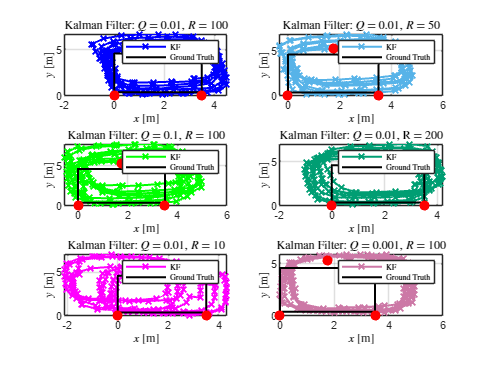


% Set the figure size
fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 27]; % This will stretch the plot across an width = 21cm, height = 29.7cm
fig.PaperSize = [20 27];

% Save the figure with the specified resolution
print(fig, 'KF_Results', '-depsc', '-r600'); % '-depsc' is used for EPS color

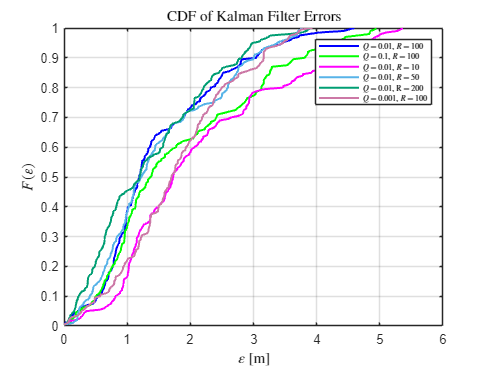

clear;
clc;
set(0,'defaulttextinterpreter','latex', 'DefaultLegendInterpreter', 'latex');

% Time increment and movement steps
time_increment = 60/110 * 1000; % converting to milliseconds
steps_left = 5;
steps_up = 6;
steps_right = 5;
steps_down = 6;
movement_distance = 0.7;

% Define the corners of the ground truth rectangle
x_true = [0, 3.50, 3.50, 0, 0];
y_true = [0.40, 0.40, 4.60, 4.60, 0.40];

node_x = [0, 3.5, 1.75];
node_y = [0, 0, 5.30];

figure;
idx = 1;
subplot_idx_raw = 1;
subplot_idx_filt = 2;

Colours = [
    0 0 1;
    0 1 0;
    1 0 1;
    0.34, 0.70, 0.91;
    0, 0.62, 0.45;
    0.80, 0.47, 0.65
    ];

% marker_styles = {'x', 'x', 'x', '+', '+', '+'};

% Loop through each file
for fileNum = 1:6
    % Construct the filename
    filename = sprintf('KF_FC132_Final%d.txt', fileNum);
    
    % Initialise arrays to hold the x, y, and t data
    x = [];
    y = [];
    t = [];
    
    % Open the file for reading
    fid = fopen(filename, 'r');
    
    % Read the file line by line
    while ~feof(fid)
        line = fgetl(fid);
        if line == -1
            break;
        end
        % Use regular expressions to extract the x, y, and t values
        matches = regexp(line, 'x = (?<x>-?\d+\.\d+), y = (?<y>-?\d+\.\d+), t = (?<t>\d+)', 'names');
        if ~isempty(matches)
            x = [x; str2double(matches.x)]; %#ok<*AGROW> 
            y = [y; str2double(matches.y)];
            t = [t; str2double(matches.t)];
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Generate the path taken
    path_x = [3.50];
    path_y = [0.40];
    path_t = [0; t(2)];
    for i = 1:(1000*1000/time_increment)
        if mod(i-1, steps_left + steps_up + steps_right + steps_down) < steps_left
            path_x(end+1, 1) = path_x(end) - movement_distance;
            path_y(end+1, 1) = path_y(end);
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up)
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) + movement_distance;
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up + steps_right)
            path_x(end+1, 1) = path_x(end) + movement_distance;
            path_y(end+1, 1) = path_y(end);
        else
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) - movement_distance;
        end
        path_t(end+1, 1) = path_t(end) + time_increment;
    end
    
    % Initialise error arrays
    error_x = [];
    error_y = [];
    error_t = [];
    total_error = [];
    
    % Find the matching time points and compute the errors
    for i = 1:length(t)
        [~, closestIndex] = min(abs(path_t - t(i)));
        if abs(path_t(closestIndex) - t(i)) <= 500 % time difference in milliseconds
            error_x(end+1, 1) = path_x(closestIndex) - x(i);
            error_y(end+1, 1) = path_y(closestIndex) - y(i);
            error_t(end+1, 1) = path_t(closestIndex) - t(i);
        end
    end

    for i = 1:length(error_x)
        total_error(i, 1) = sqrt(error_x(i).^2 + error_y(i).^2);
    end

    sorted_errors = sort(total_error);            % Sort the errors
    n = length(sorted_errors);                     % Number of error points
    p = (1:n)'/n;                                  % Probabilities for each point
    
    plot(sorted_errors, p, '-', 'LineWidth', 1.5, 'Color', Colours(fileNum, :));  % Plot CDF
    grid on;
    xlabel('$\varepsilon$ [m]');
    ylabel('$F(\varepsilon)$');
    title('CDF of Kalman Filter Errors');
    hold on
    
%     % Display the error for this file
%     fprintf('Test %d errors:\n', fileNum);
%     disp('Mean total error:')
%     disp(mean(total_error))
%     disp('STD total error:')
%     disp(std(total_error))
%     disp('Minimum total error:')
%     disp(min(total_error))
%     disp('Maximum total error:')
%     disp(max(total_error))
%     disp('Range')
%     disp(range(total_error))
%     disp('Quartiles Total Error:')
%     disp(quantile(total_error, [0.25 0.5 0.75 0.9]))
%     disp('IQR:')
%     disp(iqr(total_error))
end

hold off
legend('$Q$ = 0.01, $R$ = 100', '$Q$ = 0.1, $R$ = 100', '$Q$ = 0.01, $R$ = 10', '$Q$ = 0.01, $R$ = 50', '$Q$ = 0.01, R = 200', '$Q$ = 0.001, $R$ = 100', 'FontSize', 6)

% Set the figure size
fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 12]; % This will stretch the plot across an width = 21cm, height = 29.7cm
fig.PaperSize = [20 12];

% Save the figure with the specified resolution
print(fig, 'KF_CDF', '-depsc', '-r600'); % '-depsc' is used for EPS color